# Soluciones Numéricas para el Sistema RLC

26 de mayo de 2023

Alan Michel Carrasco Meza | José Iván Bravo Castro

En este *live script* se documentan los códigos de Matlab utilizados para la resolución de la ecuación en diferencias mediante el método de recursividad y la aproximación de sistemas en tiempo continuo desde tiempo discreto. Estos códigos no son de autoría propia, sino que fueron proporcionados por el profesor José Alberto Arellano Figueroa. Lo que sus servidores realizaron fue la documentación del código y su utilización para resolver la práctica no.4: *Transformada Z y sus aplicaciones a sistemas de tiempo discreto,  *del laboratorio de análisis de sistemas y señales.

## Solución de la Ecuación en Diferencias Finitas mediante Método de Recursividad

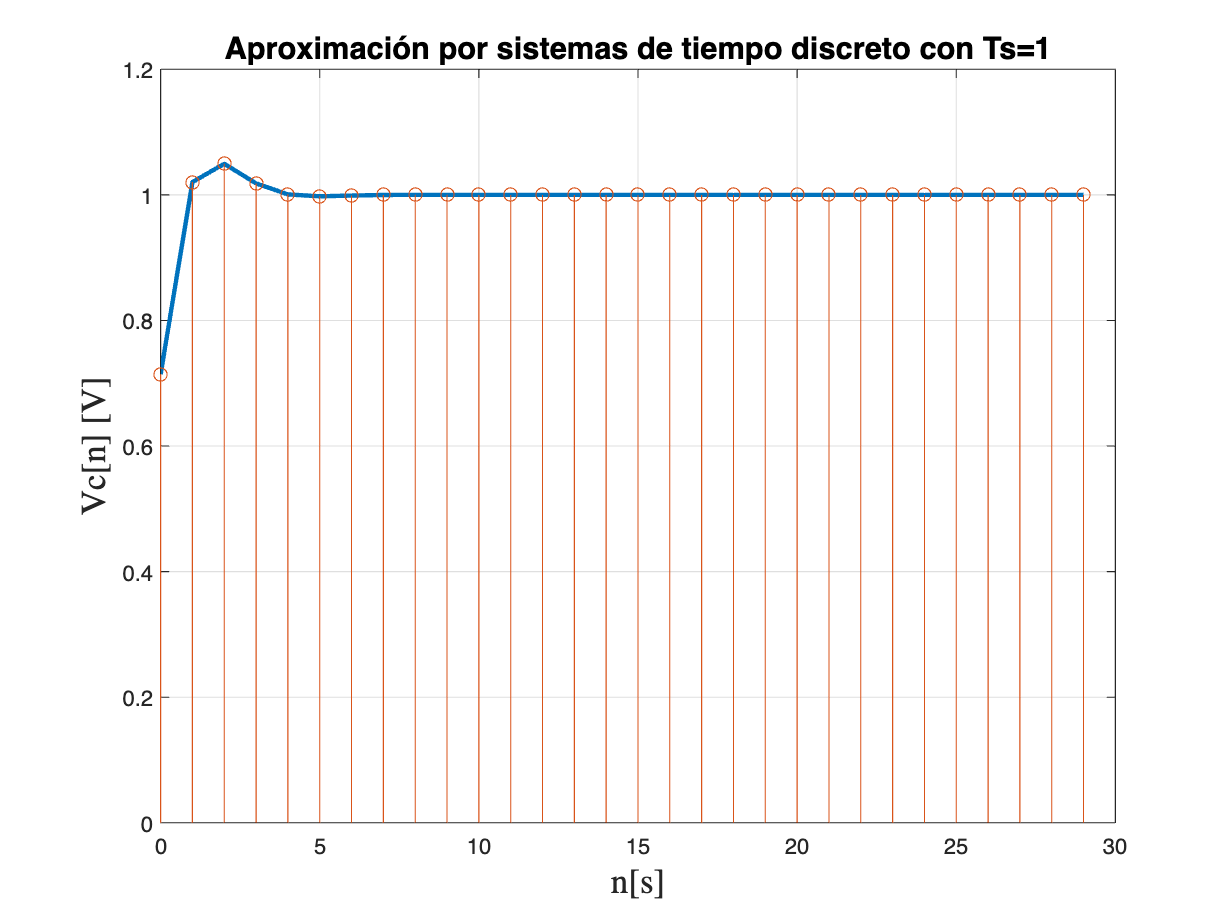

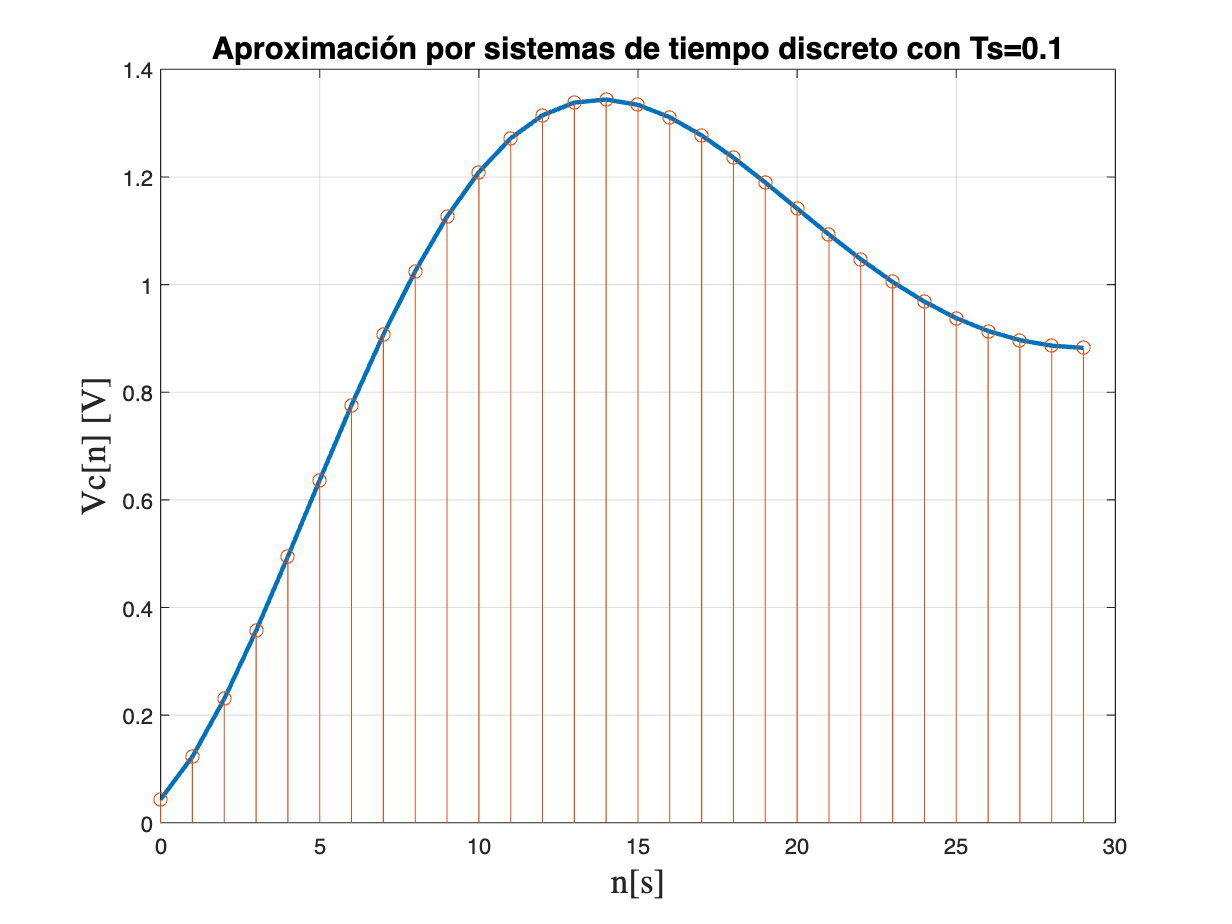

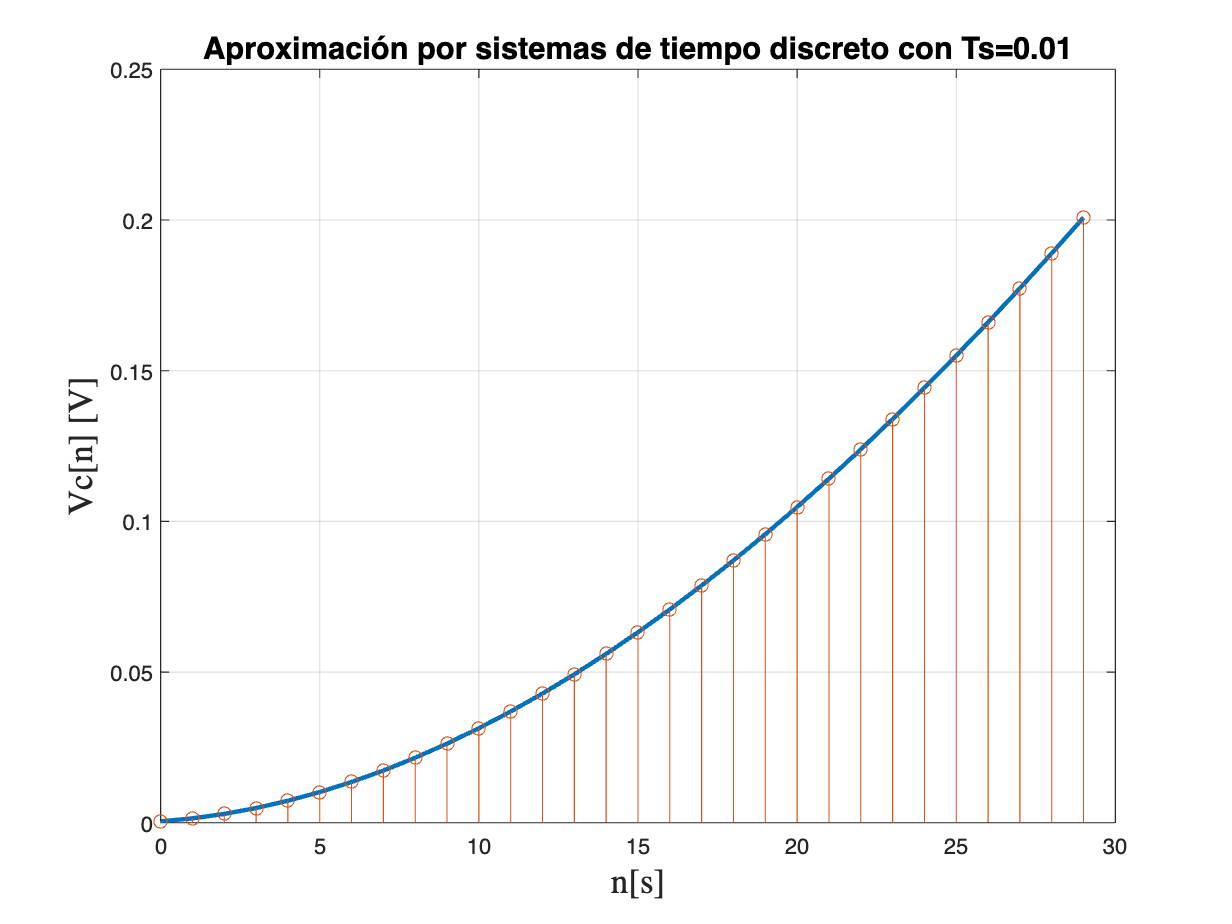

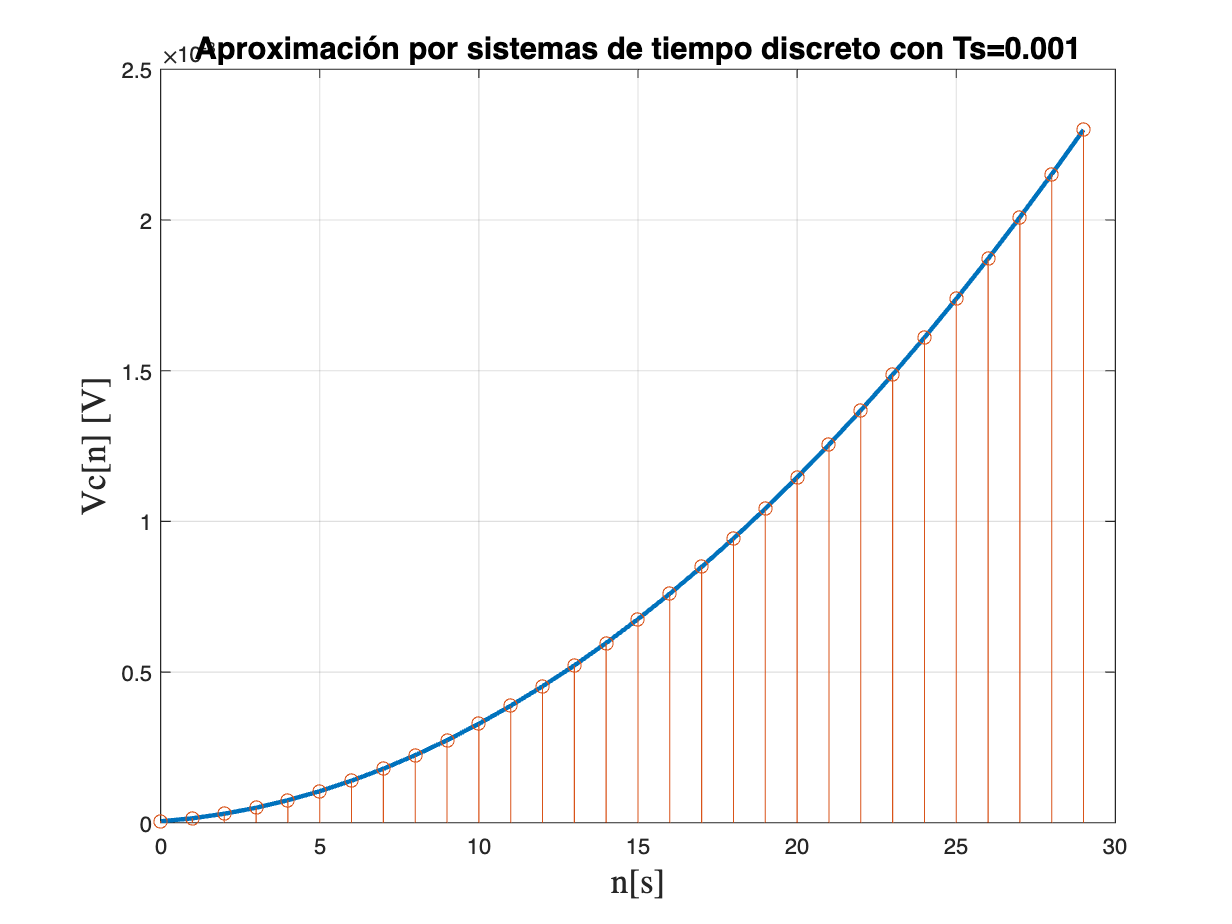

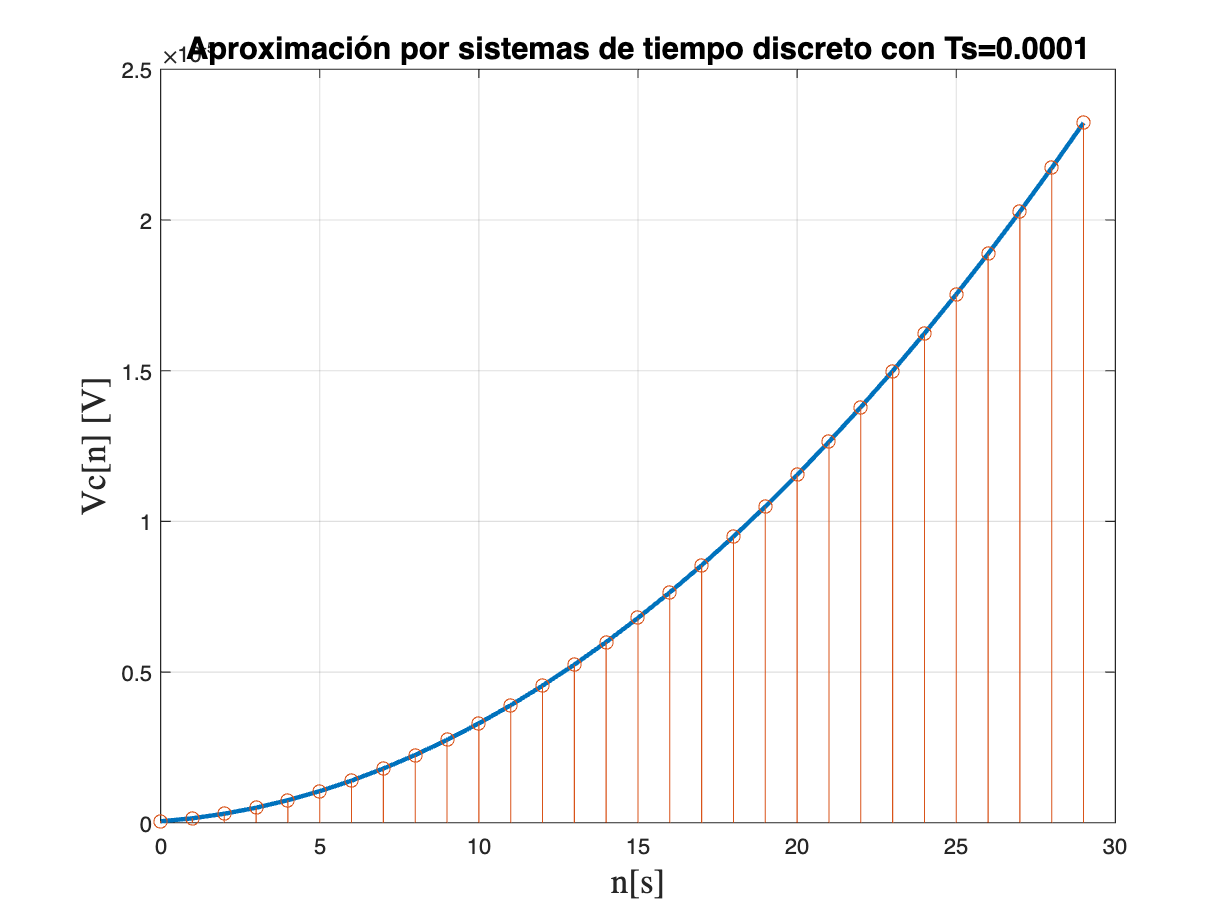

% Discretización mediante diferencias finitas y su resolución por el método de recurrencia
% Ec. General y[n]-C1y[n-1]+C2y[n-2]=d0x[n]
%Para nuestro caso Vc[n]=d0Vg[n]+C1Vc[n-1]-C2Vc[n-2]
m=30;
R=1;
L=1;
C=1/5;
a1=R/L;
a0=1/(L*C);
b0=1/(L*C);
Vc=zeros();
n=zeros();
for p=1:5 %genera los tiempos de muestreo de Ts=1 disminuyendolo en 0.1 hasta 0.0001
    figure
    Ts=10/10^p;
    [C1,C2,d0]=constantes(a1,a0,b0,Ts);

   
    for c=1:m % Se crea Vcn por el método de recurrencia
        Vc(c)=voltaje_capacitor(c-1,C1,C2,d0,1);
        n(c)=c-1;
    end
    format long
    Vc;
    plot(n,Vc,'LineWidth',2)
    hold on
    stem(n,Vc)
    grid on
    hold off
    xlabel('n[s]',FontSize=16,Interpreter='latex')
    ylabel('Vc[n] [V]',FontSize=16,Interpreter='latex')
    title(['Aproximación por sistemas de tiempo discreto con Ts=',num2str(Ts)],'FontSize',14)
end


% AproximacionDeSistemasdeTiempoContinuoPorTiempoDiscreto_2023_1
%Grafica de la Solución a la ecuación diferencial de la Actividad 1 del
%Voltaje en el Capacitor en el Sistema de 2do Orden
%d^2Vc(t)/dt^2+(R/L)dVc(t)/dt+(1/LC)Vc(t)=(1/LC)Vg(t)
%R/L=1 1/LC=5 

%Función de Transferencia en tiempo continuo
R=1; L=1; C=1/5;%Parametros
num=(1/(L*C));
den=[1 R/L 1/(L*C)];
Hs=tf(num,den)

Hs =
 
       5
  -----------
  s^2 + s + 5
 
Continuous-time transfer function.



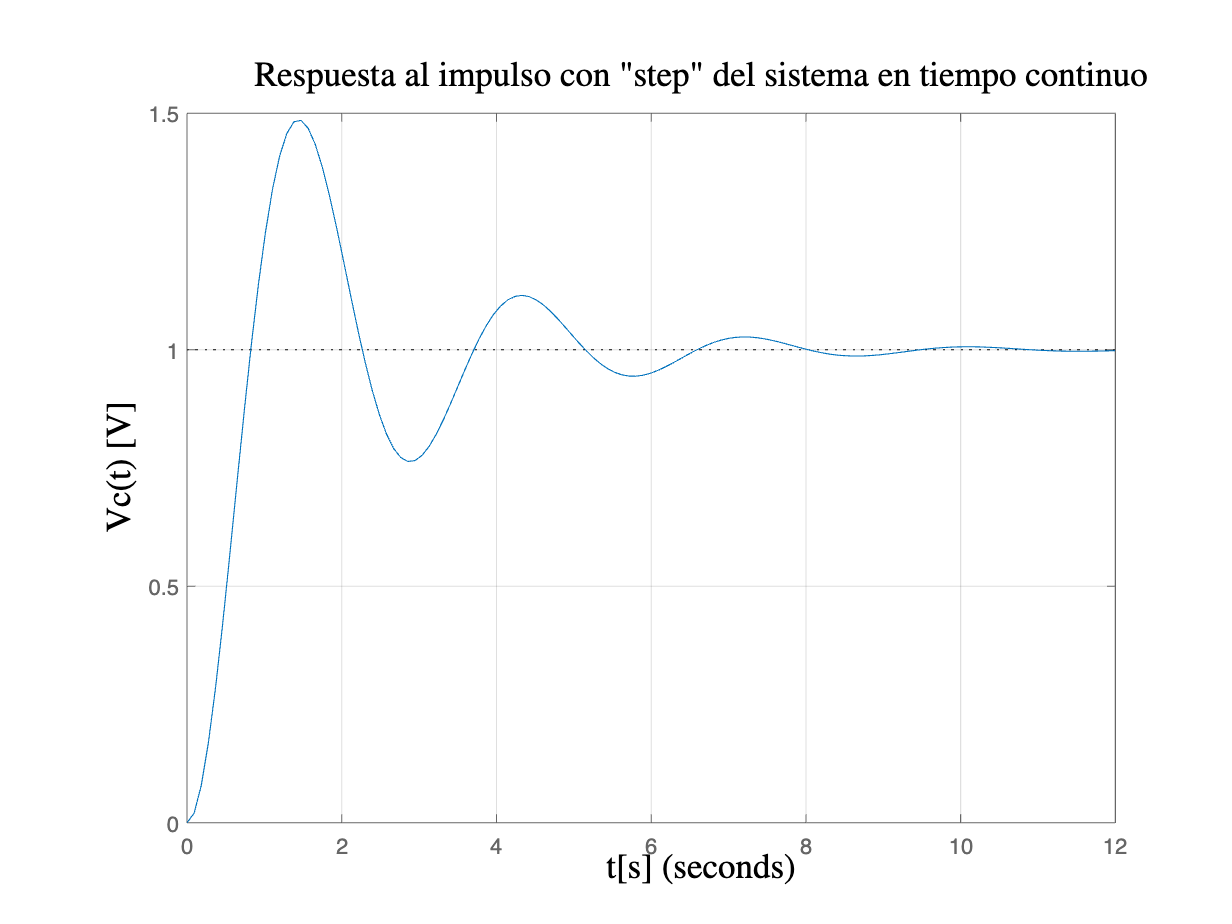

step(Hs)%Respuesta al escalón
grid on
xlabel('t[s]',FontSize=16,Interpreter='latex')%Ponle etiqueta en x
ylabel('Vc(t) [V]',FontSize=16,Interpreter='latex')%Ponle etiqueta en y
title('Respuesta al impulso con "step" del sistema en tiempo continuo','FontSize',16,Interpreter='latex')%Ponle título

Hz =
 
     1.233 z + 0.8288
  -----------------------
  z^2 + 0.6936 z + 0.3679
 
Sample time: 1 seconds
Discrete-time transfer function.



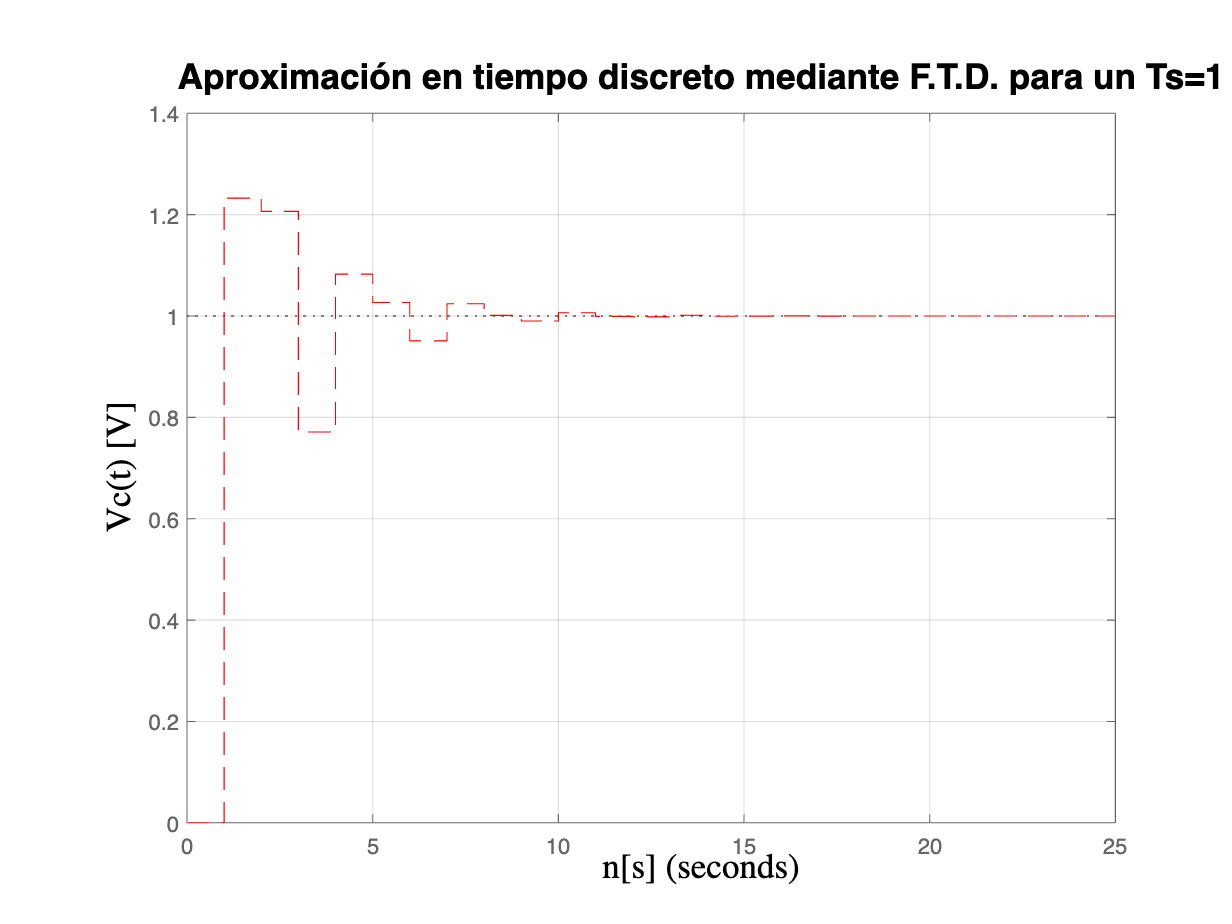

Hz =
 
    0.02409 z + 0.0233
  ----------------------
  z^2 - 1.857 z + 0.9048
 
Sample time: 0.1 seconds
Discrete-time transfer function.



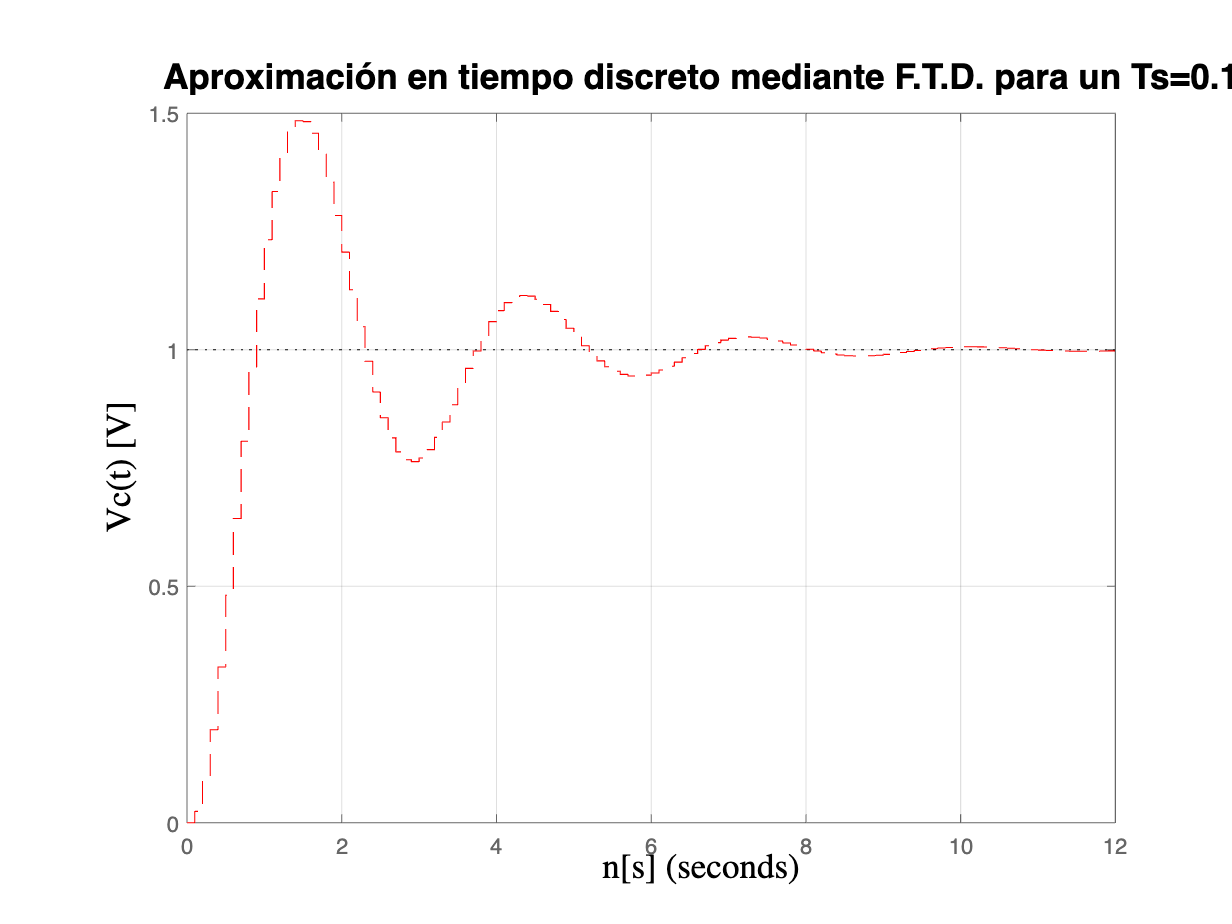

Hz =
 
  0.0002492 z + 0.0002483
  -----------------------
    z^2 - 1.99 z + 0.99
 
Sample time: 0.01 seconds
Discrete-time transfer function.



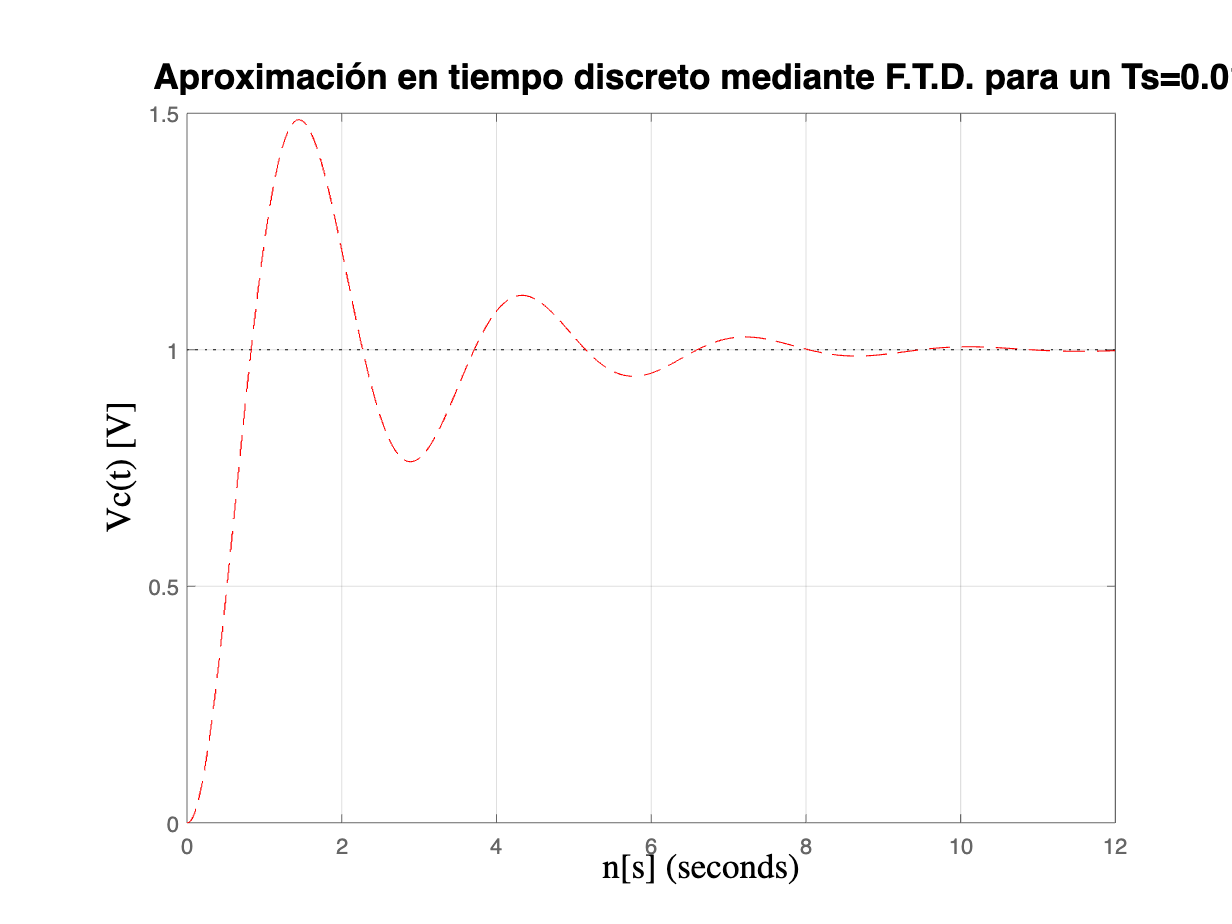

Hz =
 
  2.499e-06 z + 2.498e-06
  -----------------------
   z^2 - 1.999 z + 0.999
 
Sample time: 0.001 seconds
Discrete-time transfer function.



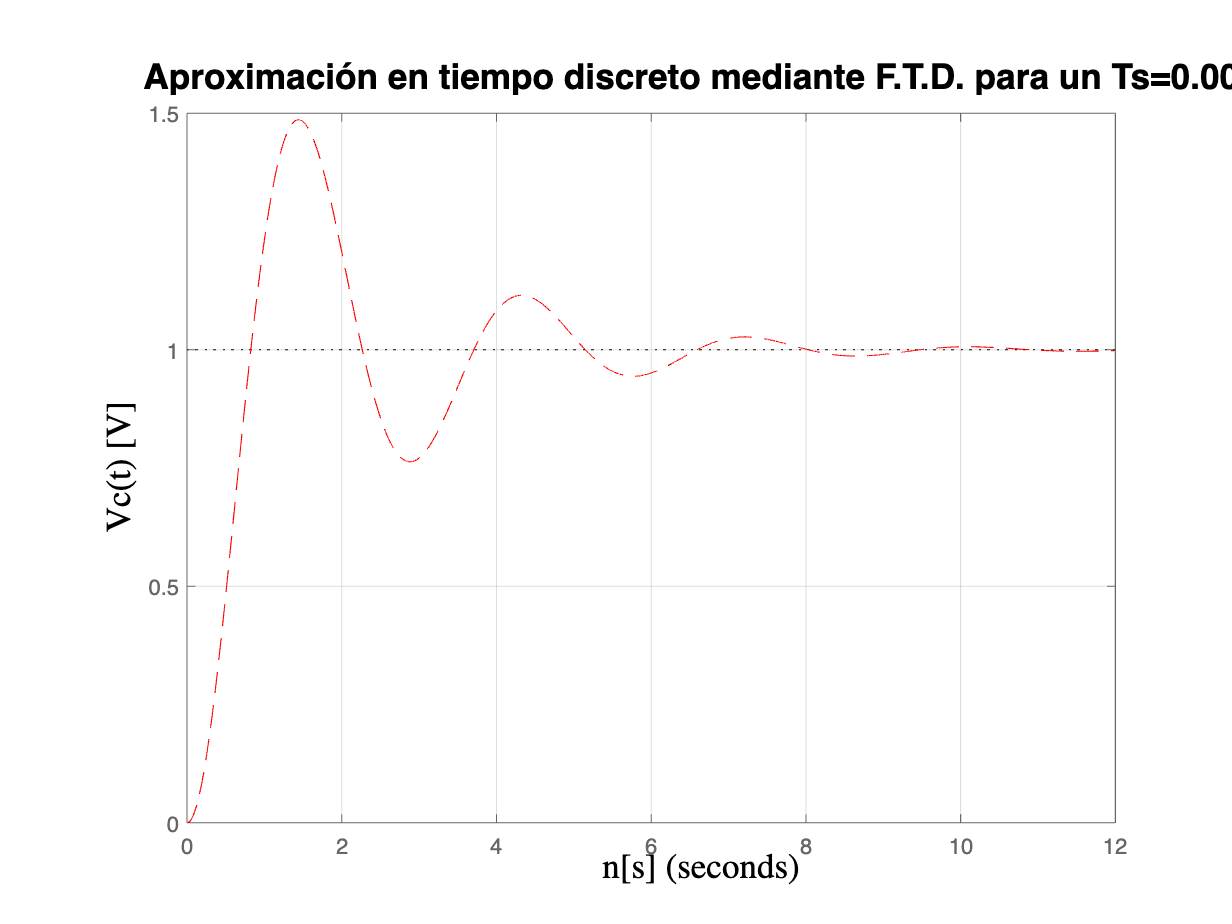

Hz =
 
  2.5e-08 z + 2.5e-08
  -------------------
  z^2 - 2 z + 0.9999
 
Sample time: 0.0001 seconds
Discrete-time transfer function.




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Función de transferencia en tiempo discreto con los distintos tiempos de
%muestreo a partir de la F.T. de tiempo continuo
%hold on
for p=1:5
    Ts=10/10^p;
    Hz=c2d(Hs,Ts,'zoh')
    figure
    step(Hz,'r --')
    grid on
    hold on
    xlabel('n[s]','FontSize',16,Interpreter='latex')
    ylabel('Vc(t) [V]',FontSize=16,Interpreter='latex')
    title(['Aproximación en tiempo discreto mediante F.T.D. para un Ts=',num2str(Ts)],FontSize=16)
end

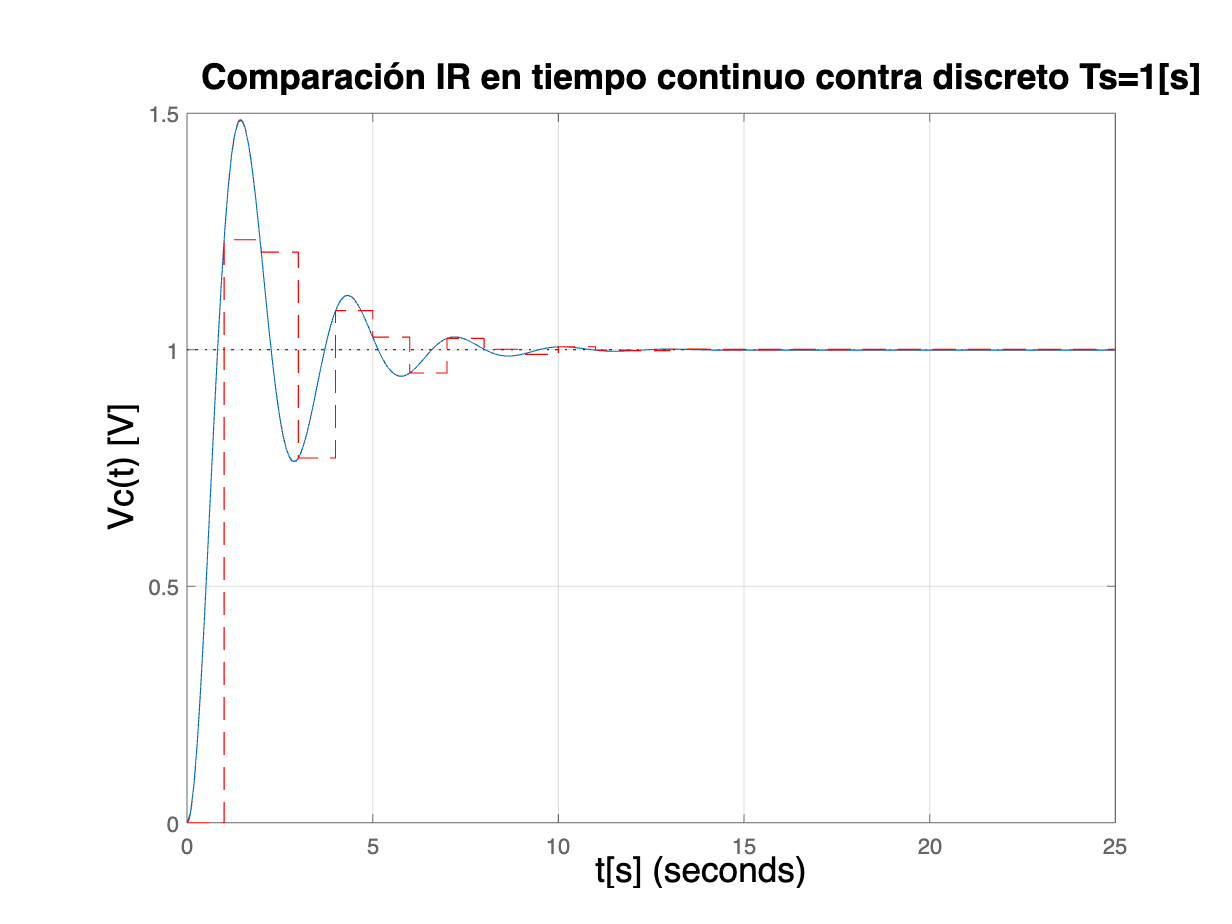

% Comparación de la respuesta al impulso en tiempo continuo contra tiempo
% discreto (Ts = 1)
% Tiempo continuo
Hs=tf(num,den);
step(Hs)%Respuesta al escalón
grid on
hold on
xlabel('t[s]',FontSize=16,Interpreter='latex')
ylabel('Vc(t) [V]',FontSize=16,Interpreter='latex')
title('Comparación IR en tiempo continuo contra discreto Ts=1[s]','FontSize',16,Interpreter='latex')%Ponle título

% Tiempo discreto
Ts = 10/10;
Hz=c2d(Hs,Ts,'zoh');
step(Hz,'r --');
hold off

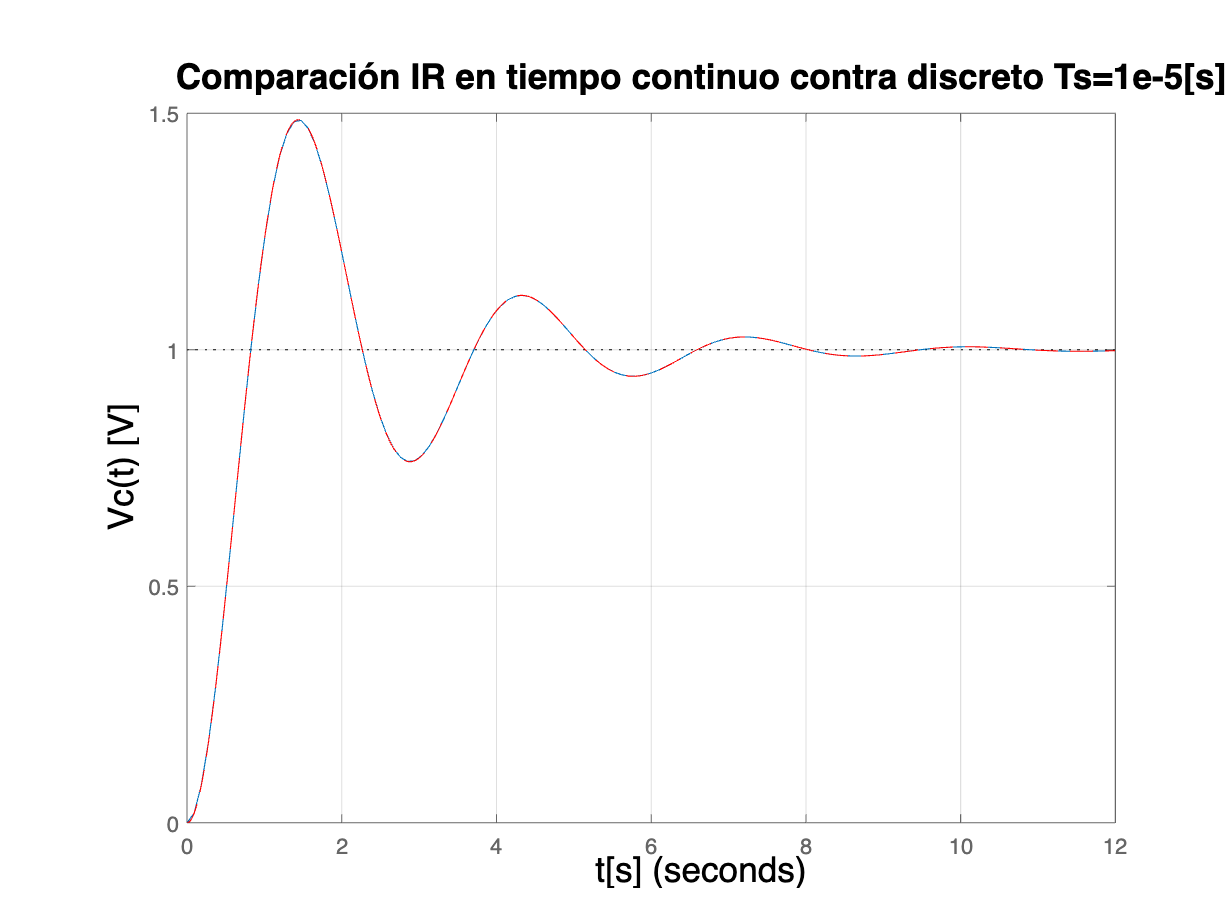

% Comparación de la respuesta al impulso en tiempo continuo contra tiempo
% discreto (Ts = 1e-5[s])
% Tiempo continuo
Hs=tf(num,den);
figure
step(Hs)%Respuesta al escalón
grid on
hold on
xlabel('t[s]',FontSize=16,Interpreter='latex')
ylabel('Vc(t) [V]',FontSize=16,Interpreter='latex')
title('Comparación IR en tiempo continuo contra discreto Ts=1e-5[s]','FontSize',16,Interpreter='latex')%Ponle título

% Tiempo discreto
Ts = 10/10^5;
Hz=c2d(Hs,Ts,'zoh');
step(Hz,'r --');